# Masseyレーティングと予測勝率を対応させる

## 2000年以降の全シーズンについてMasseyレーティングを日付ごとに算出する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');
seasonStartYearVals=unique(tbl_results.SeasonStartYear);

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
LogLossByMassey=[];    %対数損失
CalibValByMassey=[];   %較正値
LogLossByMassey_HA=[];    %対数損失
CalibValByMassey_HA=[];   %較正値


計算を早くするため，チーム名などを数値に変換しておく

matchData=zeros(size(tbl_results,1),4);
teamNames=unique(tbl_teams.TeamName);
for n1=1:size(tbl_results,1)
    TeamAName=tbl_results.Home(n1);
    TeamBName=tbl_results.Away(n1);
    TeamANum=find(teamNames== TeamAName);
    TeamBNum=find(teamNames== TeamBName);
    matchData(n1,1)=TeamANum;
    matchData(n1,2)=TeamBNum;
    matchData(n1,3)=tbl_results.HomeScore(n1);
    matchData(n1,4)=tbl_results.AwayScore(n1);
end

### 日付ごとにMasseyレーティングを計算する

- シーズンが変わった時に初期化する

- 日付が変わったらMasseyレーティングを計算する

- 予測対象試合でなくても計算しておく(予測対象試合は後で抽出しなおす)

r=zeros(size(teamNames));
r_HA=zeros(size(teamNames));    %ホームアドバンテージを考慮したレーティング
MasseyRatings=zeros(size(matchData,1),2);
tbl_results=sortrows(tbl_results,"Date");

for n1=1:size(tbl_results,1)
    if n1>1 && ...
            (tbl_results.SeasonStartYear(n1)>tbl_results.SeasonStartYear(n1-1))
        r=zeros(size(teamNames));
    end

    if n1>1 && ...
            (tbl_results.Date(n1)>tbl_results.Date(n1-1))
        % 日付が変わったのでMasseyレーティングを算出
        ind = (tbl_results.SeasonStartYear==tbl_results.SeasonStartYear(n1)) ...
            & tbl_results.Date< tbl_results.Date(n1);
        tmpMatchData=matchData(ind,:);
        X=zeros(size(tmpMatchData,1), size(teamNames,1));
        y=zeros(size(tmpMatchData,1),1);
        for n2=1:size(tmpMatchData,1)
            TeamANum=tmpMatchData(n2,1);
            TeamBNum=tmpMatchData(n2,2);
            ScoreDiff=tmpMatchData(n2,3)-tmpMatchData(n2,4);
            X(n2,TeamANum)=1;X(n2,TeamBNum)=-1;
            y(n2)=ScoreDiff;
        end
        r=pinv(X)*y;

        % ホームアドバンテージ考慮のための拡張
        X_HA=[X ones(size(X,1),1)];
        X_HA=[X_HA;ones(1,size(X_HA,2))];
        X_HA(end,end)=0;
        y_HA=[y;0];

        r_HA=pinv(X_HA)*y_HA;

    end

    TeamANum=matchData(n1,1);
    TeamBNum=matchData(n1,2);
    TeamARating=r(TeamANum);
    TeamBRating=r(TeamBNum);
    MasseyRatings(n1,1)=TeamARating;
    MasseyRatings(n1,2)=TeamBRating;

    TeamARating_HA=r_HA(TeamANum);
    TeamBRating_HA=r_HA(TeamBNum);
    MasseyRatings_HA(n1,1)=TeamARating+r_HA(end);
    MasseyRatings_HA(n1,2)=TeamBRating;


end

実際の勝敗

ActualWin=matchData(:,3)>matchData(:,4);

### シーズン開始年を指定し，シーズンごとにレーティングを変換する関数を求める

mdlParams=[];mdlParams_HA=[];
for seasonStartYearVal=seasonStartYearVals'
    seasonStartYearVal
    ind = tbl_results.SeasonStartYear==seasonStartYearVal;

seasonStartYearVal = 2000

ans = 222

mdl =     0.0000
    0.1405


mdl_HA =     0.0000
    0.1507


seasonStartYearVal = 2001

ans = 217

mdl =     0.0000
    0.1089


mdl_HA =    -0.0000
    0.1130


seasonStartYearVal = 2002

ans = 217

mdl =    -0.0000
    0.1168


mdl_HA =     0.0000
    0.1330


seasonStartYearVal = 2003

ans = 210

mdl =    -0.0000
    0.1316


mdl_HA =     0.0000
    0.1477


seasonStartYearVal = 2004

ans = 223

mdl =    -0.0000
    0.1284


mdl_HA =     0.0000
    0.1398


seasonStartYearVal = 2005

ans = 218

mdl =    -0.0000
    0.1206


mdl_HA =     0.0000
    0.1356


seasonStartYearVal = 2006

ans = 223

mdl =     0.0000
    0.1198


mdl_HA =    -0.0000
    0.1276


seasonStartYearVal = 2007

ans = 223

mdl =    -0.0000
    0.1314


mdl_HA =     0.0000
    0.1478


seasonStartYearVal = 2008

ans = 224

mdl =     0.0000
    0.1417


mdl_HA =    -0.0000
    0.1619


seasonStartYearVal = 2009

ans = 221

mdl =    -0.0000
    0.1331


mdl_HA =    -0.0000
    0.1445


seasonStartYearVal = 2010

ans = 220

mdl =    -0.0000
    0.1400


mdl_HA =     0.0000
    0.1572


seasonStartYearVal = 2011

ans = 256

mdl =    -0.0000
    0.1113


mdl_HA =     0.0000
    0.1174


seasonStartYearVal = 2012

ans = 221

mdl =     0.0000
    0.1314


mdl_HA =    -0.0000
    0.1439


seasonStartYearVal = 2013

ans = 227

mdl =    -0.0000
    0.1197


mdl_HA =     0.0000
    0.1256


seasonStartYearVal = 2014

ans = 222

mdl =     0.0000
    0.1303


mdl_HA =    -0.0000
    0.1395


seasonStartYearVal = 2015

ans = 226

mdl =     0.0000
    0.1385


mdl_HA =     0.0000
    0.1509


seasonStartYearVal = 2016

ans = 224

mdl =     0.0000
    0.1049


mdl_HA =     0.0000
    0.1112


seasonStartYearVal = 2017

ans = 216

mdl =    -0.0000
    0.1157


mdl_HA =    -0.0000
    0.1270


seasonStartYearVal = 2018

ans = 215

mdl =     0.0000
    0.1086


mdl_HA =     0.0000
    0.1178


ロジスティックモデルのパラメータ算出に利用する試合の開始日を求める

    seasonStartDate=min(tbl_results.Date(ind));

mdlParams =     0.0000    0.1405
    0.0000    0.1089
   -0.0000    0.1168
   -0.0000    0.1316
   -0.0000    0.1284
   -0.0000    0.1206
    0.0000    0.1198
   -0.0000    0.1314
    0.0000    0.1417
   -0.0000    0.1331


    predictionStartDate=seasonStartDate+days(31);

mdlParams_HA =     0.0000    0.1507
   -0.0000    0.1130
    0.0000    0.1330
    0.0000    0.1477
    0.0000    0.1398
    0.0000    0.1356
   -0.0000    0.1276
    0.0000    0.1478
   -0.0000    0.1619
   -0.0000    0.1445


テスト用(test)の試合結果の表を作る

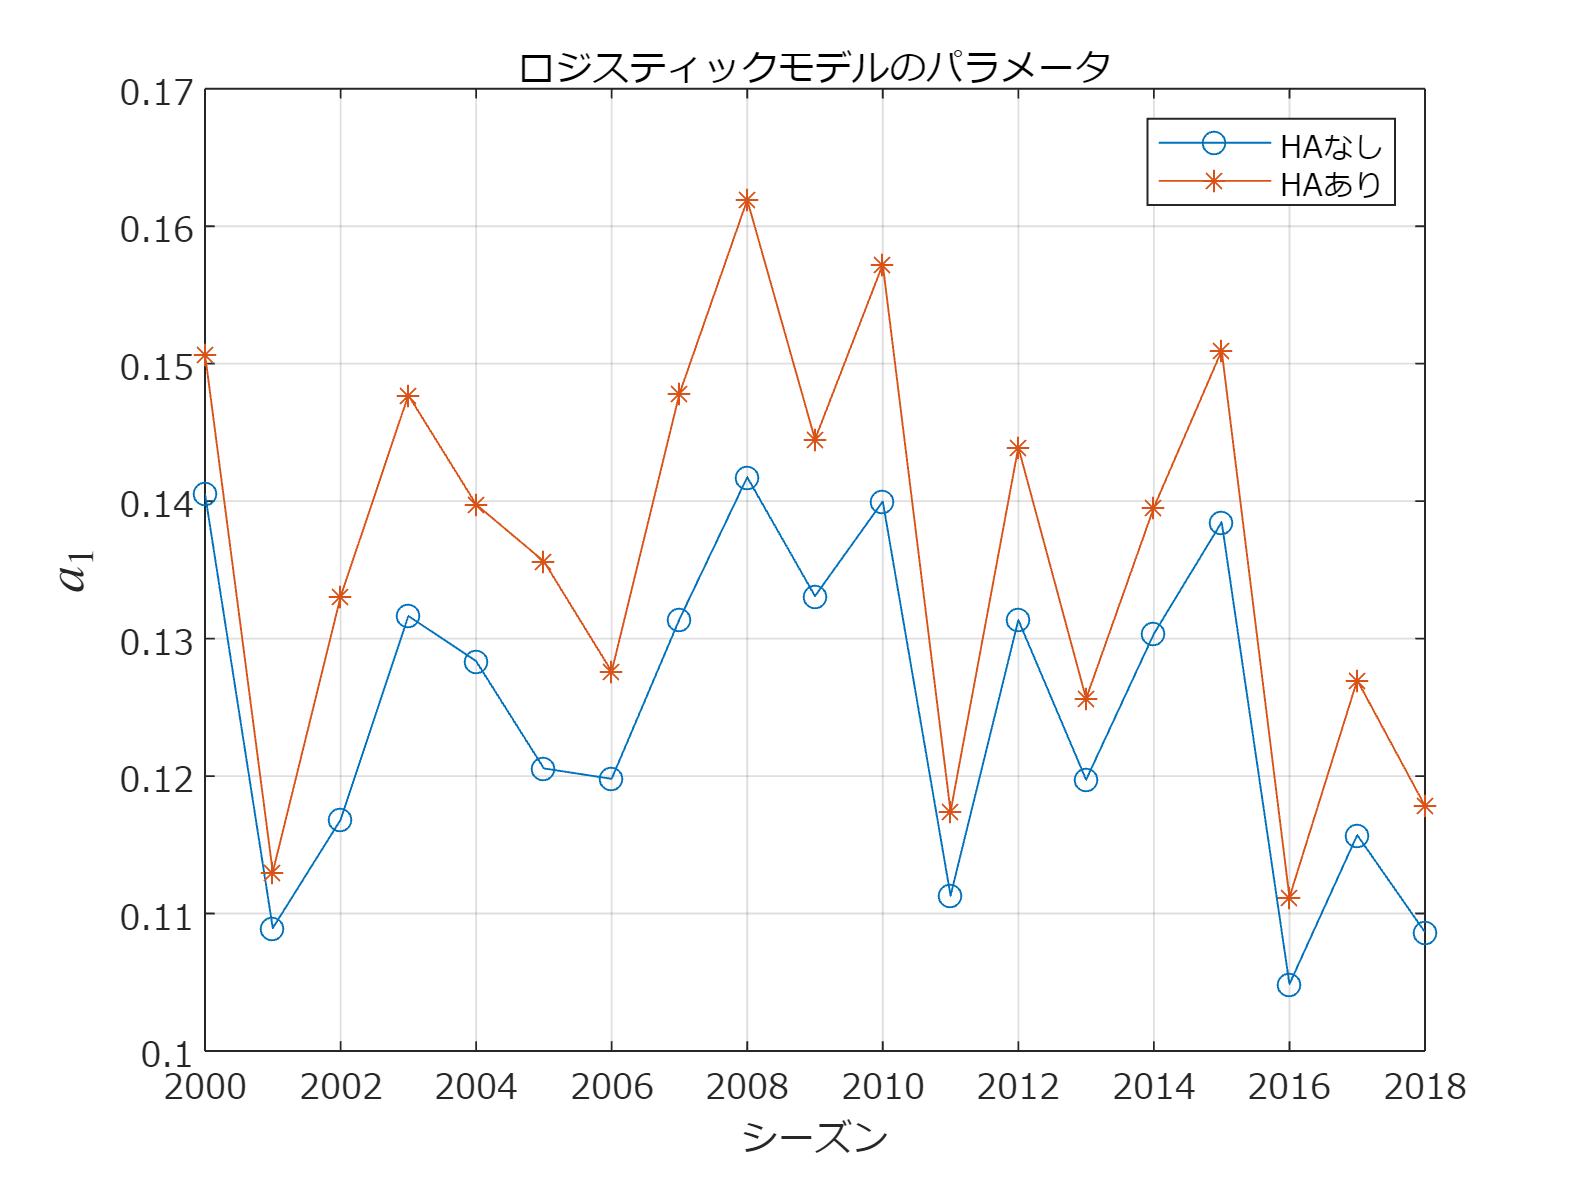

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.Date>=predictionStartDate;

    ind2=tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.Date<predictionStartDate;
    sum(ind2)

    tmpActualWin=ActualWin(ind);
    tmpActualWin=[tmpActualWin;1-tmpActualWin];
    tmpMasseyDiff=MasseyRatings(ind,1)-MasseyRatings(ind,2);

    tmpMasseyDiff=[tmpMasseyDiff;-tmpMasseyDiff];
    tmpMasseyDiff_HA=MasseyRatings_HA(ind,1)-MasseyRatings_HA(ind,2);
    tmpMasseyDiff_HA=[tmpMasseyDiff_HA;-tmpMasseyDiff_HA];
    mdl=glmfit(tmpMasseyDiff, tmpActualWin,"binomial","link","logit")
    mdlParams=[mdlParams; mdl'];
    mdl_HA=glmfit(tmpMasseyDiff_HA, tmpActualWin,"binomial","link","logit")
    mdlParams_HA=[mdlParams_HA;mdl_HA'];
end
mdlParams
mdlParams_HA

シーズンごとのロジスティック回帰モデルを図示する

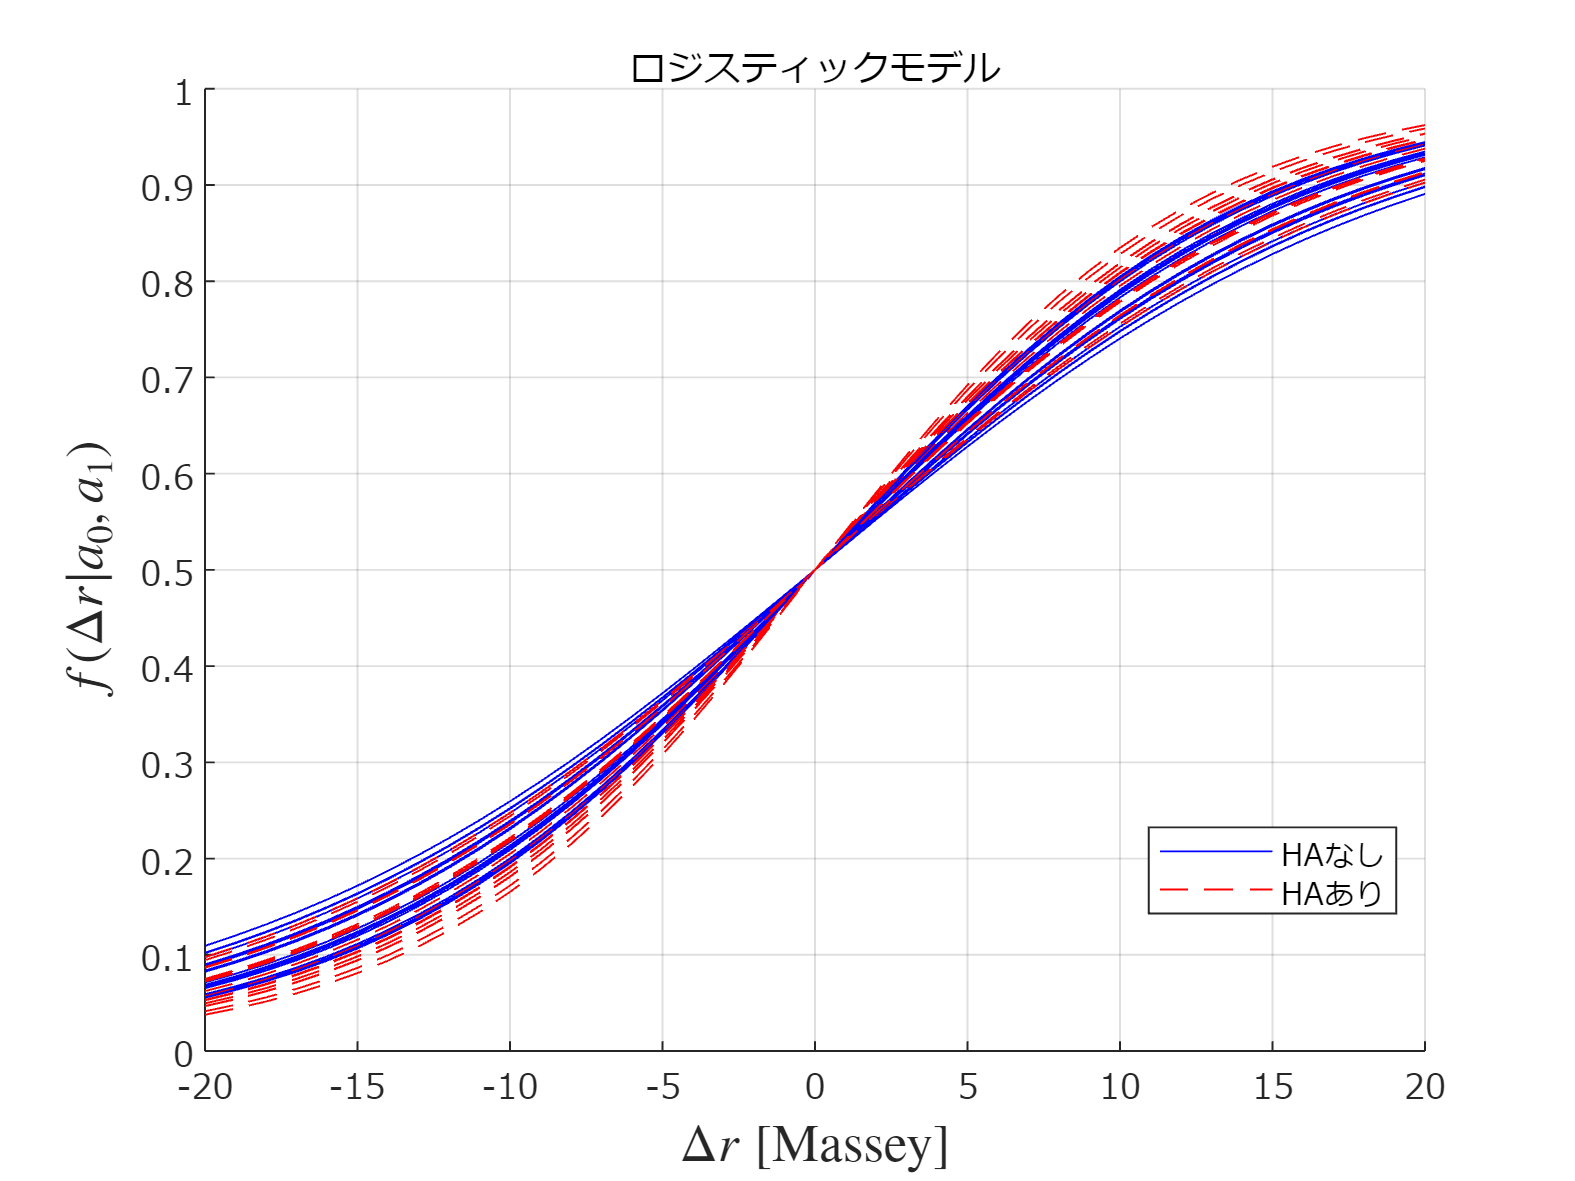

figure
plot(seasonStartYearVals,mdlParams(:,2),'o-');hold on;
plot(seasonStartYearVals,mdlParams_HA(:,2),'*-');
set(gca,'fontname','メイリオ');
grid on;

xlabel('シーズン');
ylabel('$a_1$','Interpreter','latex','FontSize',14);
title('ロジスティックモデルのパラメータ');
legend({'HAなし','HAあり'},'Location','northeast');
exportgraphics(gcf,'fig_NBAPrediction_LogisticModelParams.pdf');

bins=-20:20;
figure
hold on;
for n1=1:size(mdlParams,1)
    plot(bins, glmval(mdlParams(n1,:)',bins,'logit'),'b-');
    plot(bins, glmval(mdlParams_HA(n1,:)',bins,'logit'),'r--');
end
set(gca,'fontname','メイリオ');
grid on;
xlabel('$\Delta r$ [Massey]','Interpreter','latex','FontSize',14);
ylabel('$f(\Delta r| a_0, a_1)$','Interpreter','latex','FontSize',14);
title('ロジスティックモデル');
legend({'HAなし','HAあり'},'Location','best');
exportgraphics(gcf,'fig_NBAPrediction_LogisticModelFunction.pdf');

seasonStartYearVal = 2003

indSeasonStarYear = 4

mdl =    -0.0000
    0.1221


mdl_HA =    -0.0000
    0.1323


seasonStartYearVal = 2004

indSeasonStarYear = 5

mdl =    -0.0000
    0.1191


mdl_HA =     0.0000
    0.1313


seasonStartYearVal = 2005

indSeasonStarYear = 6

mdl =    -0.0000
    0.1256


mdl_HA =     0.0000
    0.1402


seasonStartYearVal = 2006

indSeasonStarYear = 7

mdl =    -0.0000
    0.1269


mdl_HA =     0.0000
    0.1410


seasonStartYearVal = 2007

indSeasonStarYear = 8

mdl =    -0.0000
    0.1229


mdl_HA =     0.0000
    0.1343


seasonStartYearVal = 2008

indSeasonStarYear = 9

mdl = 2×1
   -0.0000
    0.1239


mdl_HA = 2×1
    0.0000
    0.1370


seasonStartYearVal = 2009

indSeasonStarYear = 10

mdl = 2×1
    0.0000
    0.1310


mdl_HA = 2×1
   -0.0000
    0.1458


seasonStartYearVal = 2010

indSeasonStarYear = 11

mdl = 2×1
   -0.0000
    0.1354


mdl_HA = 2×1
   -0.0000
    0.1514


seasonStartYearVal = 2011

indSeasonStarYear = 12

mdl = 2×1
   -0.0000
    0.1383


mdl_HA = 2×1
   -0.0000
    0.1545


seasonStartYearVal = 2012

indSeasonStarYear = 13

mdl = 2×1
   -0.0000
    0.1281


mdl_HA = 2×1
    0.0000
    0.1397


seasonStartYearVal = 2013

indSeasonStarYear = 14

mdl = 2×1
   -0.0000
    0.1275


mdl_HA = 2×1
    0.0000
    0.1395


seasonStartYearVal = 2014

indSeasonStarYear = 15

mdl = 2×1
   -0.0000
    0.1208


mdl_HA = 2×1
    0.0000
    0.1290


seasonStartYearVal = 2015

indSeasonStarYear = 16

mdl = 2×1
   -0.0000
    0.1271


mdl_HA = 2×1
   -0.0000
    0.1364


seasonStartYearVal = 2016

indSeasonStarYear = 17

mdl = 2×1
    0.0000
    0.1295


mdl_HA = 2×1
    0.0000
    0.1387


seasonStartYearVal = 2017

indSeasonStarYear = 18

mdl = 2×1
    0.0000
    0.1246


mdl_HA = 2×1
    0.0000
    0.1339


seasonStartYearVal = 2018

indSeasonStarYear = 19

mdl = 2×1
    0.0000
    0.1197


mdl_HA = 2×1
    0.0000
    0.1297


「直前3シーズンのパラメータの平均」を予測モデルとして採用することとし，予測性能を測る

for seasonStartYearVal=seasonStartYearVals(4:end)'
    seasonStartYearVal
    indSeasonStarYear=find(seasonStartYearVals==seasonStartYearVal)
    mdl=mean(mdlParams((indSeasonStarYear-3):(indSeasonStarYear-1),:))'
    mdl_HA=mean(mdlParams_HA((indSeasonStarYear-3):(indSeasonStarYear-1),:))'
    ind = tbl_results.SeasonStartYear==seasonStartYearVal;

予測対象の開始日を求める

    seasonStartDate=min(tbl_results.Date(ind));
    predictionStartDate=seasonStartDate+days(31);

テスト用(test)の試合結果の表を作る

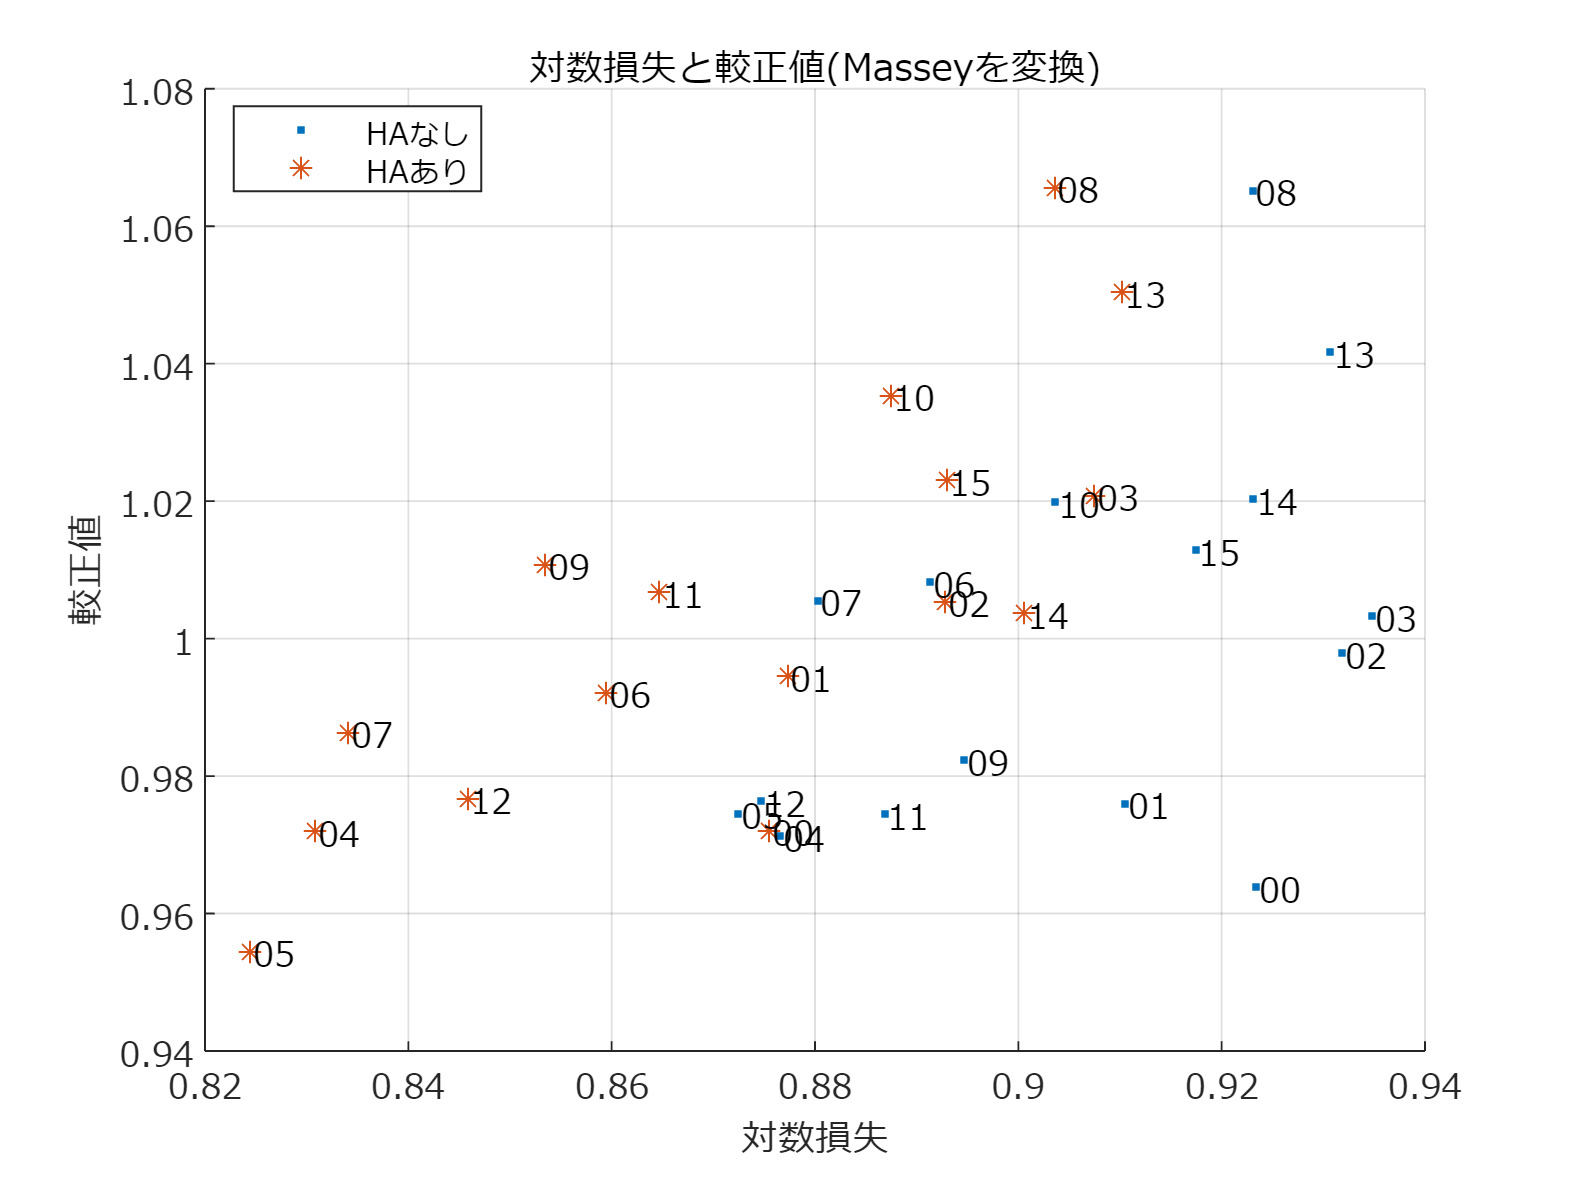

    ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
        & tbl_results.Date>=predictionStartDate;


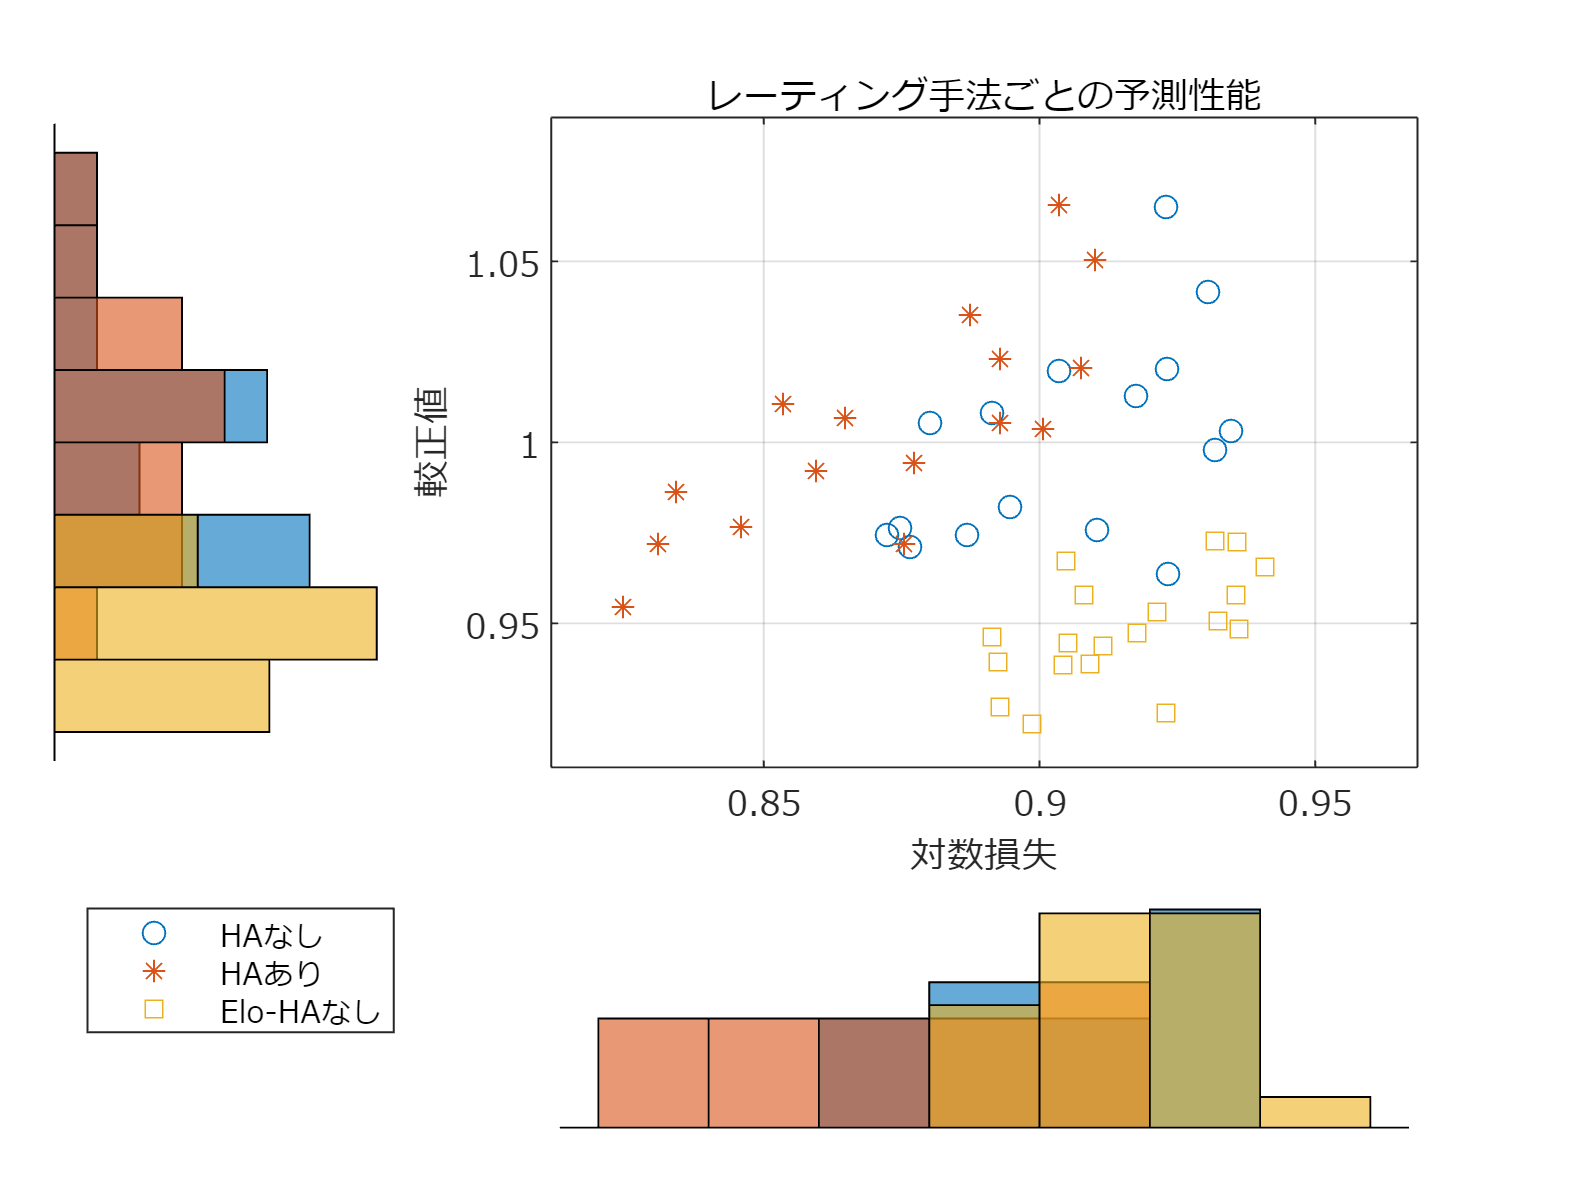

    PredictedMatches=[PredictedMatches;sum(ind)];
    w=ActualWin(ind);
    RateDiff=MasseyRatings(ind,1)-MasseyRatings(ind,2);
    RateDiff_HA=MasseyRatings_HA(ind,1)-MasseyRatings_HA(ind,2);
    wHat=glmval(mdl, RateDiff,'logit');
    wHat_HA=glmval(mdl_HA, RateDiff_HA,'logit');
    tmpLogLoss=-mean(w.*log2(wHat)+(1-w).*log2(1-wHat));    %対数損失
    LogLossByMassey =[LogLossByMassey;tmpLogLoss];
    tmpLogLoss=-mean(w.*log2(wHat_HA)+(1-w).*log2(1-wHat_HA));    %対数損失
    LogLossByMassey_HA =[LogLossByMassey_HA;tmpLogLoss];


    ind2=wHat>0.5;  %ホームチームを優位と予測した試合
    tmpSumActualWin=sum(w(ind2))+sum(1-w(~ind2));  %優位チームの実際の勝利数
    tmpSumPredWin=sum(wHat(ind2))+sum(1-wHat(~ind2));   %優位チームの勝率の合計
    tmpCalibVal=tmpSumPredWin/tmpSumActualWin;

    CalibValByMassey=[CalibValByMassey;tmpCalibVal];

    ind2=wHat_HA>0.5;  %ホームチームを優位と予測した試合
    tmpSumActualWin=sum(w(ind2))+sum(1-w(~ind2));  %優位チームの実際の勝利数
    tmpSumPredWin=sum(wHat_HA(ind2))+sum(1-wHat_HA(~ind2));   %優位チームの勝率の合計
    tmpCalibVal=tmpSumPredWin/tmpSumActualWin;
    CalibValByMassey_HA=[CalibValByMassey_HA;tmpCalibVal];

end
figure
scatter(LogLossByMassey, CalibValByMassey,'.');
hold on;grid on;
scatter(LogLossByMassey_HA, CalibValByMassey_HA,'*');
set(gca,'fontname','メイリオ');
text(LogLossByMassey+0.0002, CalibValByMassey, ...
    num2str(seasonStartYearVals(4:end)-(2000+3),'%02d'),'FontName','メイリオ');
text(LogLossByMassey_HA+0.0002, CalibValByMassey_HA, ...
    num2str(seasonStartYearVals(4:end)-(2000+3),'%02d'),'FontName','メイリオ');
xlabel('対数損失');ylabel('較正値');title('対数損失と較正値(Masseyを変換)');
legend({'HAなし','HAあり'},'Location','best');
exportgraphics(gcf,'fig_NBAPredictionByMasseyTransformed-LogLoss-CalibVal.pdf');

周辺化したヒストグラムを伴う散布図として描き直す

load('../data/data_NBAPredictionByElo.mat');
figure;
scatterhist([LogLossByMassey;LogLossByMassey_HA;LogLossByElo], ...
    [CalibValByMassey;CalibValByMassey_HA;CalibValByElo],...
    'Group', ...
    [zeros(size(LogLossByMassey));ones(size(LogLossByMassey_HA)); ...
    2*ones(size(LogLossByElo))], ...
    'Style','bar','Marker','o*s');
grid on;
set(gca,'fontname','メイリオ');
xlabel('対数損失');ylabel('較正値');
legend({'HAなし','HAあり','Elo-HAなし'});
title('レーティング手法ごとの予測性能')
exportgraphics(gcf,'fig_NBAPredictionByMasseyTransformed-LogLoss-CalibVal-scatterhist.pdf');